# Tarea 1b

Ricardo Camacho Castillo 

A01654132

clc,clear

## Dominio

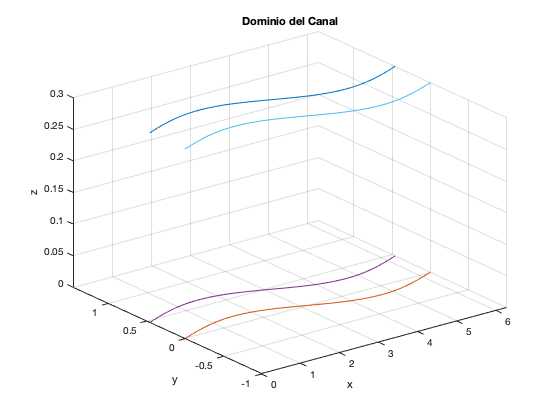

t = linspace(0,2*pi,100);
m = zeros(100);

p = 0.46;
q = 0.3;
n = q*ones(100);

xd = t;
yd = (1/6)*sin(t);
zd = m;

x1d = t;
y1d = (1/6)*sin(t)+p;
z1d = m;

x2d = t;
y2d = (1/6)*sin(t);
z2d = n;

x3d = t;
y3d = (1/6)*sin(t)+p;
z3d = n;

plot3(xd,yd,zd)
hold on 
grid on
plot3(x1d,y1d,z1d)

plot3(x2d,y2d,z2d)
plot3(x3d,y3d,z3d)

xlabel('x')
ylabel('y')
zlabel('z')
title('Dominio del Canal')
ylim([-1 1+p])
xlim([0 2*pi])
hold off

r =10;

x = linspace(0,2*pi,r);

y1 = (1/6)*sin(x);
y2 = (1/6)*sin(x)+.46;

Yg = [];

Xg = meshgrid(x);

for i=1:r
    X(:,:,i)=Xg ;
end

for i=1:r
    v = linspace(y1(i),y2(i),r);
    d = [v'];
    Yg = [Yg,d];
end

for i=1:r
    Y(:,:,i)=Yg ;
end

z = linspace(0,0.3,r);

for k=1:r
    for i=1:r
        for j=1:r
            Zm(i,j) = z(k);
        end
    end
    Z(:,:,k)=Zm;
end

u = 10*ones(r);

for i=1:r
    f1(:,:,i)=u;
end

f2 = 10*(1/6)*cos(X);
f3 = Z*0;

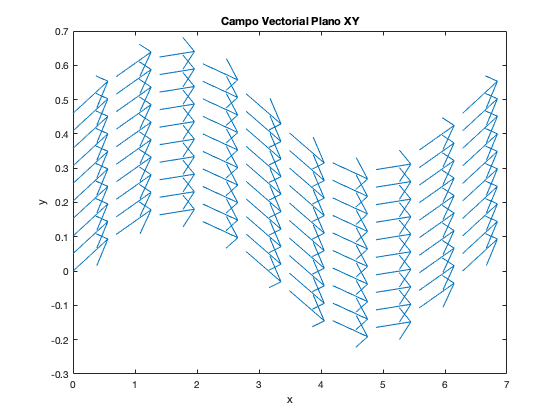


X1 = X(:,:,1);
Y1 = Y(:,:,1);
f11 = 10*ones(r);
f21 = 10*(1/6)*cos(X1);

quiver(X1,Y1,f11,f21)
xlabel('x')
ylabel('y')
title('Campo Vectorial Plano XY')

Xp = linspace(0,2*pi,10);
Yp = (1/6)*cos(Xp);
Vp = [Xp',Yp'];
Vp;

Vp =          0    0.1667
    0.6981    0.1277
    1.3963    0.0289
    2.0944   -0.0833
    2.7925   -0.1566
    3.4907   -0.1566
    4.1888   -0.0833
    4.8869    0.0289
    5.5851    0.1277
    6.2832    0.1667


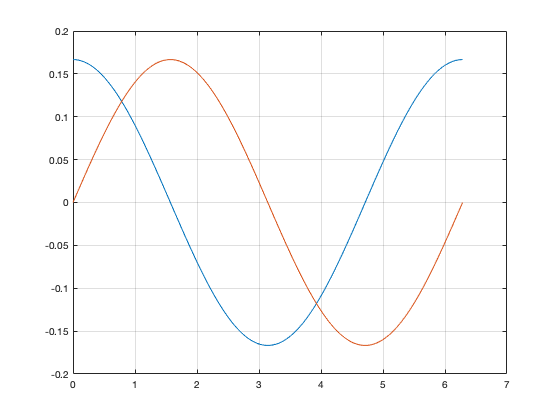

Xp1 = linspace(0,2*pi,1000);
Yp2 = (1/6)*cos(Xp1);
Yp1 = (1/6)*sin(Xp1);
plot(Xp1,Yp2)
hold on
grid on
plot(Xp1,Yp1)
hold off

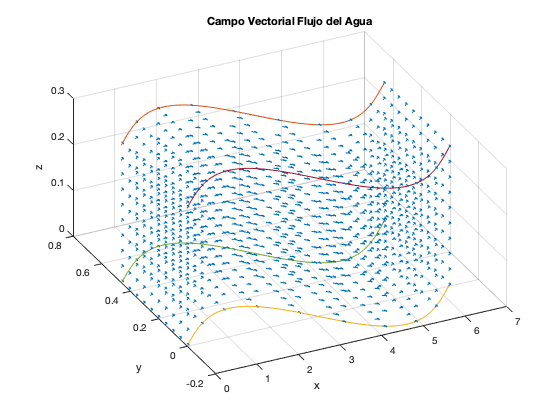

quiver3(X,Y,Z,f1,f2,f3)
hold on
title('Campo Vectorial Flujo del Agua')
xlabel('x')
ylabel('y')
zlabel('z')
plot3(xd,yd,zd)
grid on
plot3(x1d,y1d,z1d)

plot3(x2d,y2d,z2d)
plot3(x3d,y3d,z3d)